clc; clear; close all;

% Cargar datos
data = readtable('Five_times_Kinematics_HT_Query_final.xlsx');


fprintf('Dimensiones del dataset: %d filas x %d columnas\n', size(data,1), size(data,2));

Dimensiones del dataset: 46 filas x 81 columnas


disp('Variables del dataset:');

Variables del dataset:


disp(data.Properties.VariableNames);

    {'reclutado'}    {'AgeGroup'}    {'BMI_Value'}    {'GroupName'}    {'x1_AAFEM'}    {'x2_AAFEM'}    {'x4_AAFEM'}    {'x5_AAFEM'}    {'x1_AAIEM'}    {'x2_AAIEM'}    {'x3_AAIEM'}    {'x4_AAIEM'}    {'x5_AAIEM'}    {'x2_AKFEM'}    {'x3_AKFEM'}    {'x4_AKFEM'}    {'x5_AKFEM'}    {'x1_AKAAM'}    {'x2_AKAAM'}    {'x3_AKAAM'}    {'x4_AKAAM'}    {'x1_AKIEM'}    {'x2_AKIEM'}    {'x3_AKIEM'}    {'x4_AKIEM'}    {'x5_AKIEM'}    {'x1_AHPFEM'}    {'x2_AHPFEM'}    {'x3_AHPFEM'}    {'x4_AHPFEM'}    {'x5_AHPFEM'}    {'x2_AHPAAM'}    {'x3_AHPAAM'}    {'x4_AHPAAM'}    {'x5_AHPAAM'}    {'x1_AHPIEM'}    {'x3_AHPIEM'}    {'x4_AHPIEM'}    {'x5_AHPIEM'}    {'x1_APTILTM'}    {'x2_APTILTM'}    {'x3_APTILTM'}    {'x4_APTILTM'}    {'x5_APTILTM'}    {'x1_APOBLIM'}    {'x2_APOBLIM'}    {'x3_APOBLIM'}    {'x4_APOBLIM'}    {'x1_APROTM'}    {'x2_APROTM'}    {'x3_APROTM'}    {'x4_APROTM'}    {'x5_APROTM'}    {'x1_ASPMLM'}    {'x2_ASPMLM'}    {'x3_ASPMLM'}    {'x4_ASPMLM'}    {'x5_ASPMLM'}    {'x2_ASPIEM'}    {'x3_AS


% Seleccionar columnas numéricas
isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 78 dimensiones.


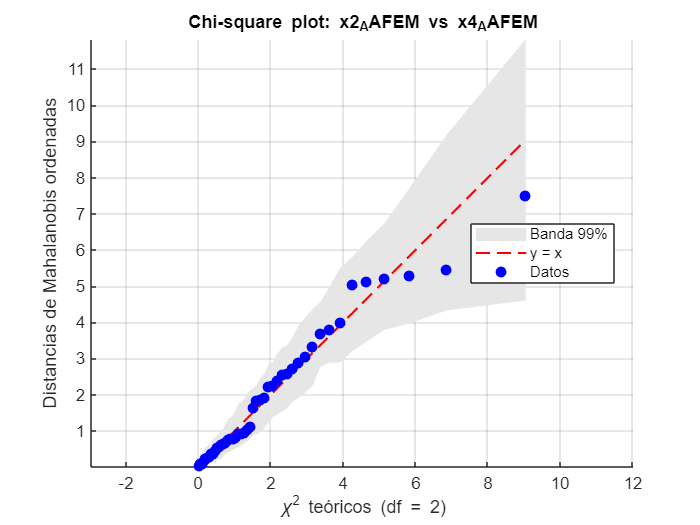

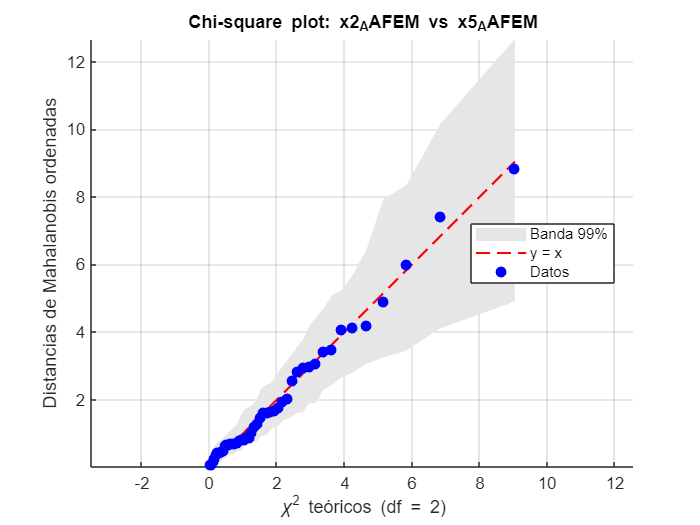

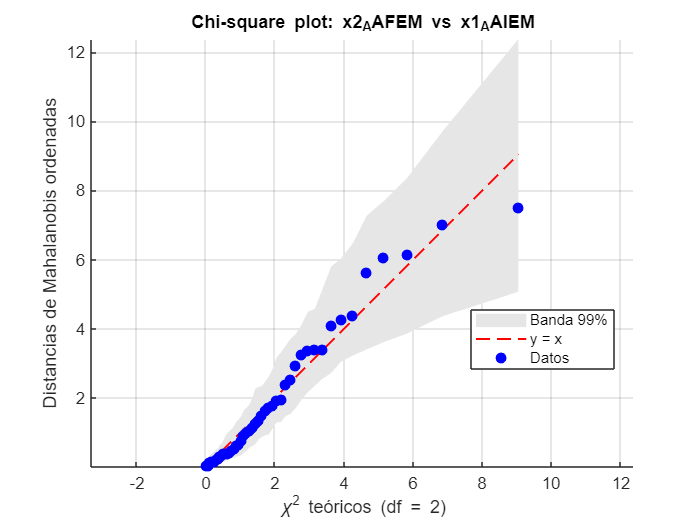

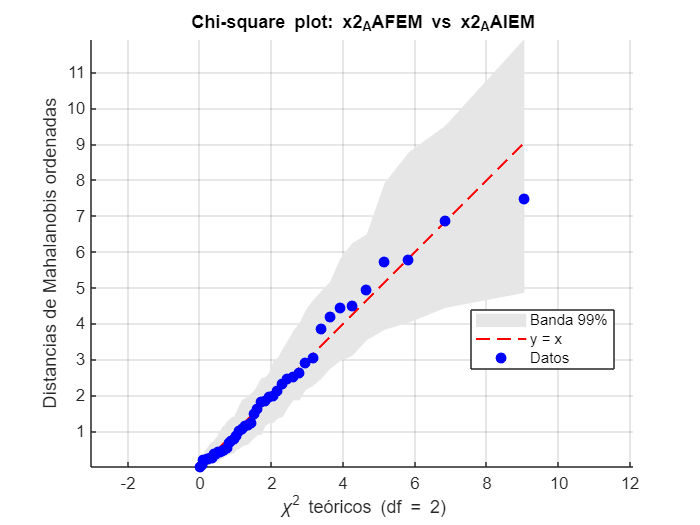

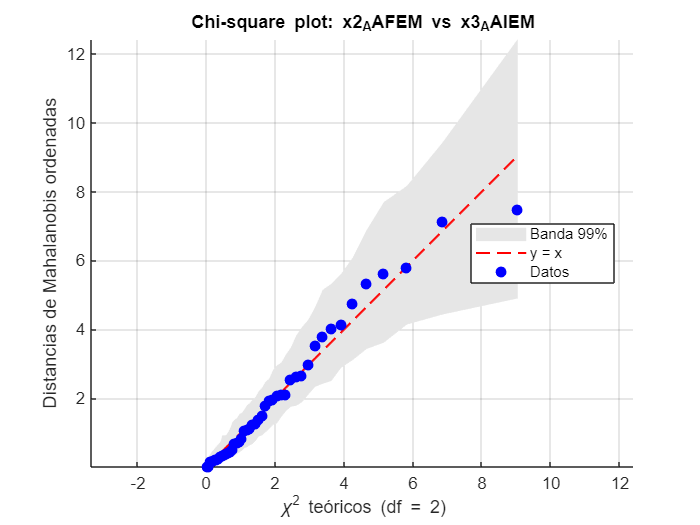

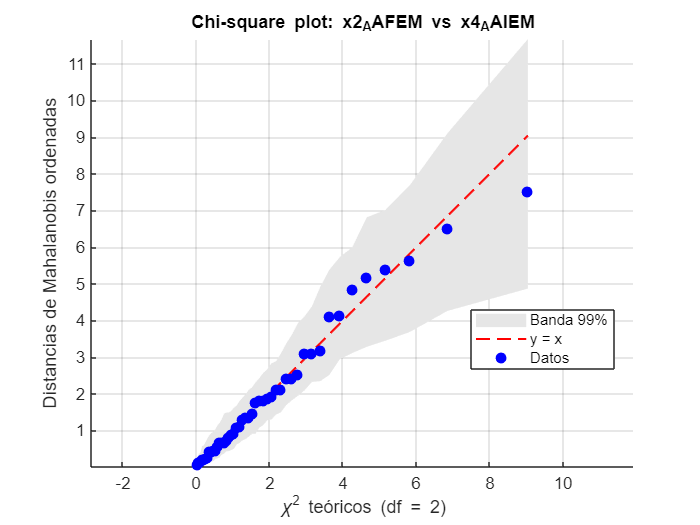

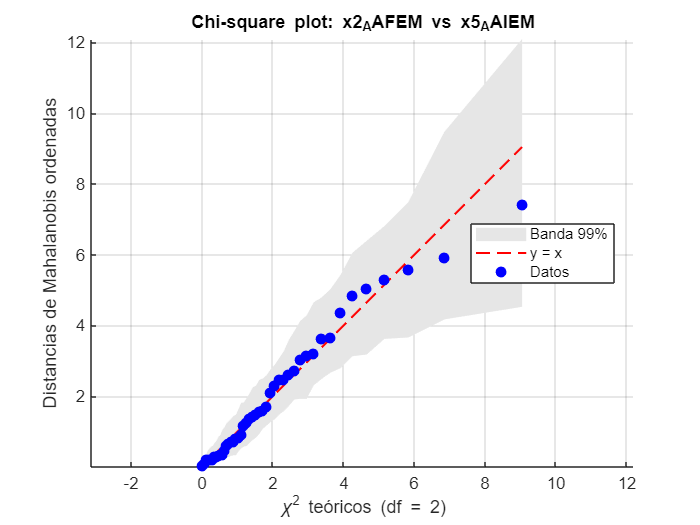

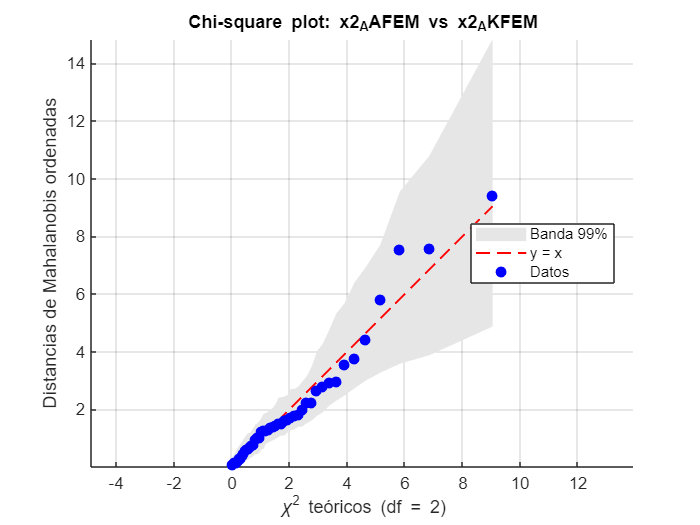


% Parámetros de bootstrap
B = 500;                   % número de réplicas
alpha = 0.01;              % nivel de significancia
lower_p = alpha/2;
upper_p = 1 - alpha/2;

% -----------------------------
% Chi-square plots bivariados
% Comparar variable 3 con todas las siguientes (desde la 4)
% -----------------------------
dim_interes = 3;

for j = 4:p
    % Extraer submatriz bivariada
    X_sub = [X(:, dim_interes), X(:, j)];  % n x 2

    % Estadísticos de ajuste
    mean_vec = mean(X_sub);
    cov_mat   = cov(X_sub);
    inv_cov   = pinv(cov_mat);

    % Distancias de Mahalanobis observadas
    D2_obs = zeros(n,1);
    for i = 1:n
        d = X_sub(i,:) - mean_vec;
        D2_obs(i) = d * inv_cov * d';
    end
    D2_obs_sorted = sort(D2_obs);

    % Cuantiles teóricos chi² (df = 2)
    chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);

    % -----------------------------
    % Bootstrap no paramétrico para la banda
    % -----------------------------
    D2_boot = zeros(n, B);
    for b = 1:B
        % Re-muestreo con reemplazo
        idx = randi(n, n, 1);
        Xb = X_sub(idx, :);

        % Media y covarianza del bootstrap
        mean_b = mean(Xb);
        cov_b = cov(Xb);
        inv_cov_b = pinv(cov_b);

        % Calcular distancias Mahalanobis bootstrap
        db_mat = Xb - mean_b;
        D2b = sum((db_mat * inv_cov_b) .* db_mat, 2);
        D2_boot(:,b) = sort(D2b);
    end

    % Calcular percentiles fila a fila
    lower_env = quantile(D2_boot, lower_p, 2);
    upper_env = quantile(D2_boot, upper_p, 2);

    % -----------------------------
    % Gráfico con banda de confianza
    % -----------------------------
    varName_i = numericData.Properties.VariableNames{dim_interes};
    varName_j = numericData.Properties.VariableNames{j};

    figure;
    hold on;
    % Banda gris
    fill( [chi2_q; flipud(chi2_q)], ...
          [lower_env; flipud(upper_env)], ...
          [0.9 0.9 0.9], 'EdgeColor','none');
    % Línea identidad
    plot(chi2_q, chi2_q, 'r--', 'LineWidth',1.2);
    % Datos observados
    plot(chi2_q, D2_obs_sorted, 'bo', 'MarkerFaceColor','b');
    hold off;

    axis equal; grid on;
    xlabel('\chi^2 teóricos (df = 2)');
    ylabel('Distancias de Mahalanobis ordenadas');
    title(sprintf('Chi-square plot: %s vs %s', varName_i, varName_j));
    legend('Banda 99%','y = x','Datos', 'Location','best');
end